# 图像复原

## 噪声模型

% 使用 imnoise 添加噪声
% imnoise(f, type, param)

% 5.2.2 指定分布产生空间随机噪声
% 例 5.1 讲清楚了课上提到的瑞丽分布他的随机变量的公式怎么来的(从分布函数求随机变量)
% 所以对应的分布，我们感兴趣的随机变量公式就能求出，表 5.1 有罗列
% rand 矩阵元素都是 0,1 内的均匀分布
A = rand(2, 2)

A =     0.1447    0.5342
    0.8150    0.7252


A = randn(2, 2) % 矩阵元素为 0 均值，单位方差的正态数

A =    -0.6253   -1.0833
   -0.9050   -0.7675


% find 函数
A = [11 22 33; 44 55 66; 77 88 0];
I = find(A); % 返回矩阵元素所有索引，拉直了矩阵
A(I); % 列优先遍历！且是非零元素的索引
[r, c] = find(A); % 非零元素行和列索引, 也是列优先的逻辑
[r, c, v] = find(A);
I = find(A < 88);
A(I) = 100;
A

A =    100   100   100
   100   100   100
   100    88   100


% 例 5.2 imnoise2 生成直方图
figure;

r1 = imnoise2('gaussian', 10000, 1, 0, 1);
r2 = imnoise2('uniform', 10000, 1);
r3 = imnoise2('lognormal', 10000, 1);
r4 = imnoise2('rayleigh', 10000, 1);
r5 = imnoise2('exponential', 10000, 1);
r6 = imnoise2('erlang', 10000, 1);

R =     0.5603
    0.6402
    0.0195
    0.2676
    2.3778
    0.1023
    0.4164
    0.0487
    1.8959
    0.8936


R =     1.5407
    0.6915
    0.3293
    1.5080
    3.6938
    0.1615
    1.1972
    0.1433
    3.0330
    0.9870


R =     1.6427
    0.9270
    0.6071
    1.7753
    3.7908
    0.3883
    1.8079
    0.8048
    3.0599
    1.6456


R =     2.6232
    1.7723
    2.0070
    2.3511
    3.9397
    0.4302
    1.9046
    2.2565
    3.1039
    2.2032


R =     2.7086
    1.8664
    2.0230
    2.9092
    4.2214
    1.1064
    1.9140
    4.1603
    3.2529
    2.7919


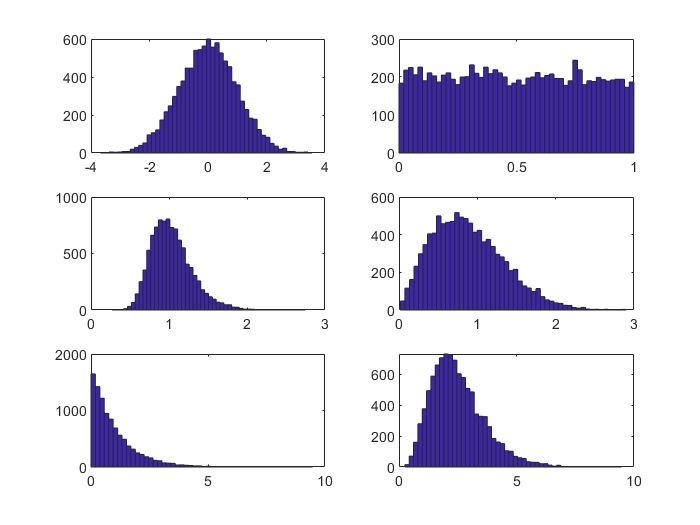

% hist 绘制直方图，区别 imhist
subplot(3, 2, 1);
hist(r1, 50);
subplot(3, 2, 2);
hist(r2, 50);
subplot(3, 2, 3);
hist(r3, 50);
subplot(3, 2, 4);
hist(r4, 50);
subplot(3, 2, 5);
hist(r5, 50);
subplot(3, 2, 6);
hist(r6, 50);

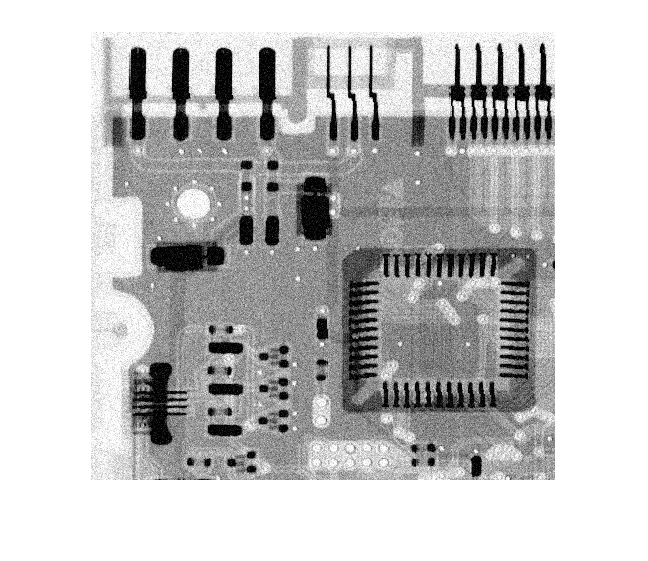

% 5.2.3 周期噪声
% 例 5.3 使用 imnoise3 跳过

% 5.2.4 估计噪声参数
% 利用图像估计均值，方差，直方图，在估计求解 a b(表 5.1)
f = imread('./DIP-Ex/pic/dipum_images_ch05/Fig0504(a)(noisy_image).tif');
figure;
imshow(f, []);

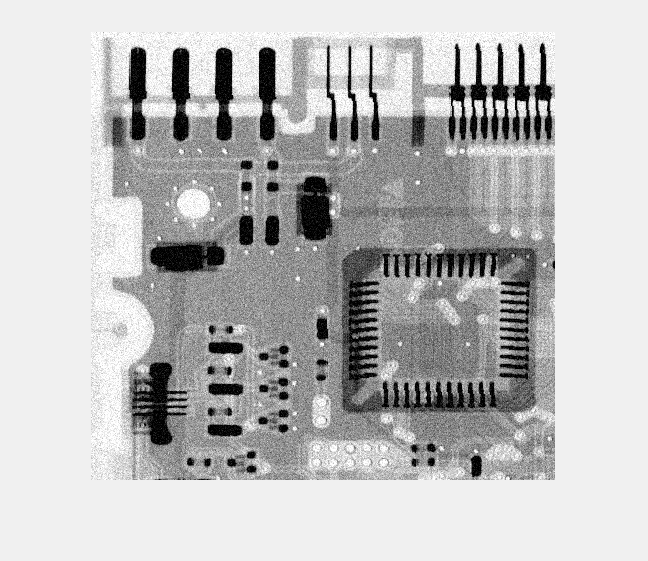

figure;
[B, c, r] = roipoly(f); % 交互式产生 mask

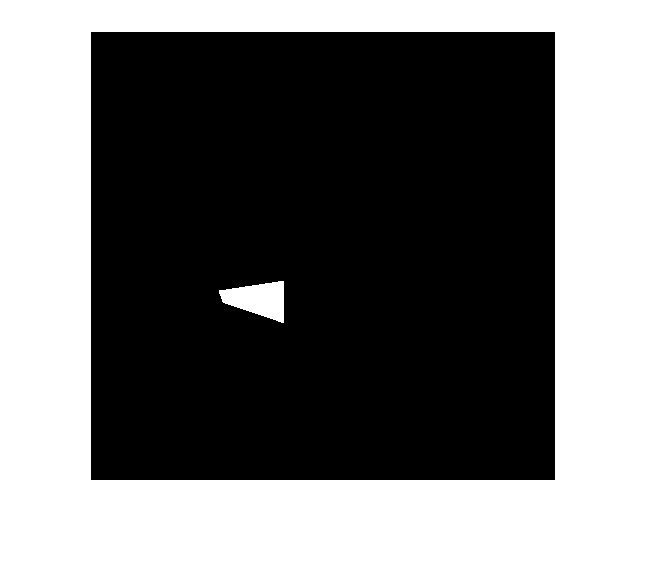

figure;
imshow(B);

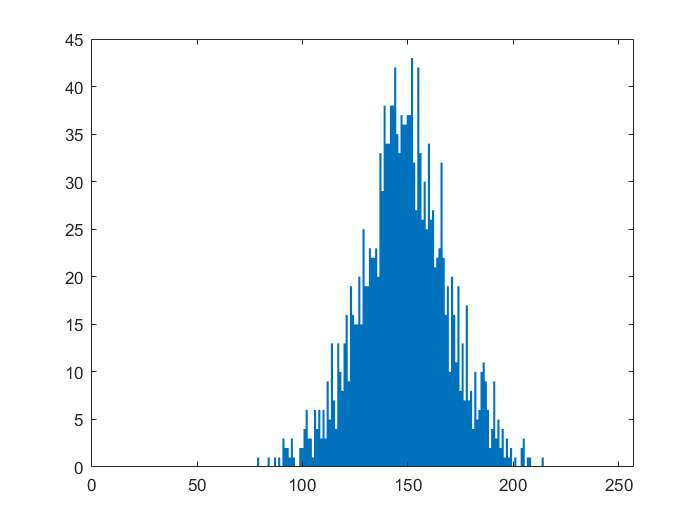

[p, npix] = histroi(f, c, r);
figure, bar(p, 1); % 通过 roipoly 选取背景

[v, unv] = statmoments(p, 2);
v

v =     0.5775    0.0064


unv % 均值，方差

unv =   147.2703  414.9049


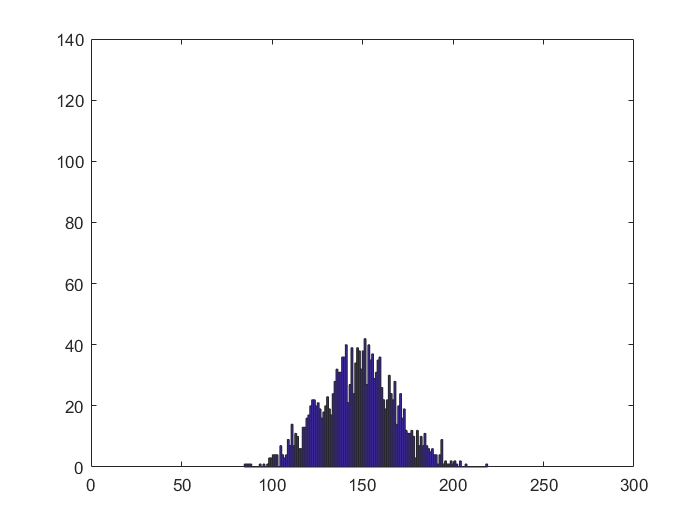

% 用构造噪声模型和依据统计得到的均值方差，得到了类似的高斯分布
X = imnoise2('gaussian', npix, 1, 147, 20); % 方差在 unv(2) 基础上修改
figure, hist(X, 130); % 不是 imhist，imhist 输入图片统计灰度值个数
axis([0 300 0 140]); 

## 仅有噪声复原 —— 空间滤波

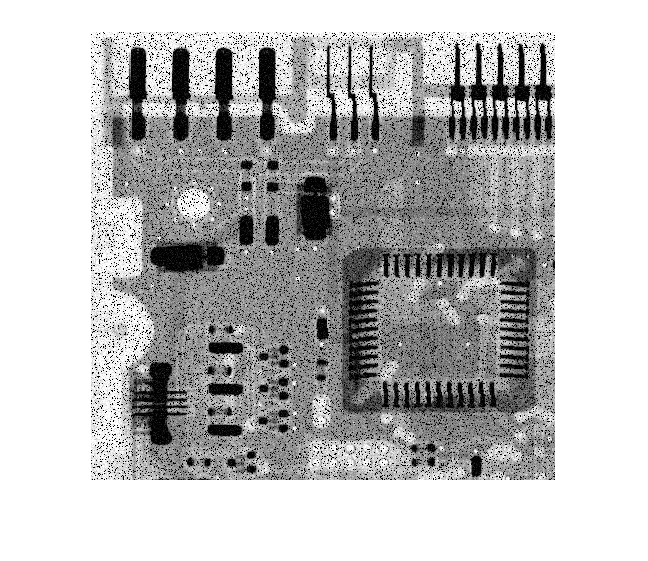

% 例 5.5 
f = imread('./DIP-Ex/pic/dipum_images_ch05/Fig0504(a)(noisy_image).tif');
figure;
% 注意式子得到的差别， 1 和 2 式是一致的。
% g = imfilter(0.1 * f, ones(3, 3), 'replicate');
% g = imfilter(f, 0.1 * ones(3, 3), 'replicate');
% g = imfilter(f, ones(3, 3), 'replicate');imshow(g);

[M, N] = size(f);
R = imnoise2('salt & pepper', M, N, 0.1, 0); % 概率 0.1 的椒噪声
% 污染椒噪声的手法
c = find(R == 0); % R 中 0 的都是处理为椒噪声。
gp_0 = f;
gp_0(c) = 0; % 把对应出变黑色，就是椒噪声。 
imshow(gp_0);

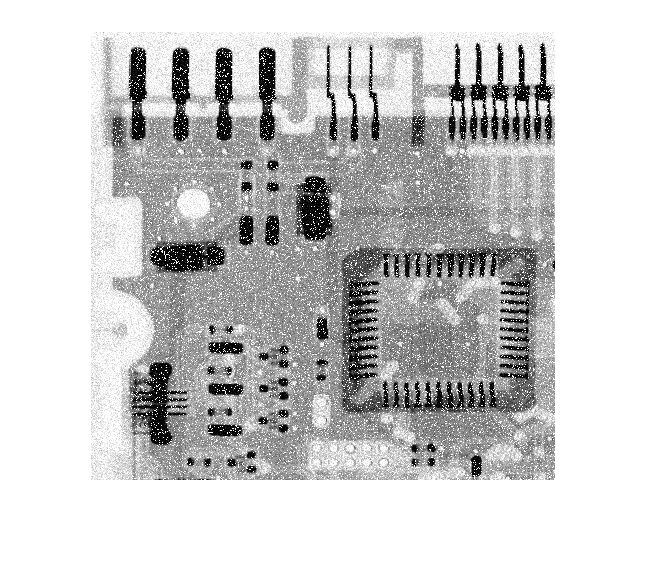

% 污染盐噪声
R = imnoise2('salt & pepper', M, N, 0, 0.1); % 盐噪声概率 0.1
c = find(R == 1);
gp_255 = f;
% ! gp(c) = 1; 这里错了！！是要弄成白色，白色是 255！！！
gp_255(c) = 255;
figure;
imshow(gp_255, []);

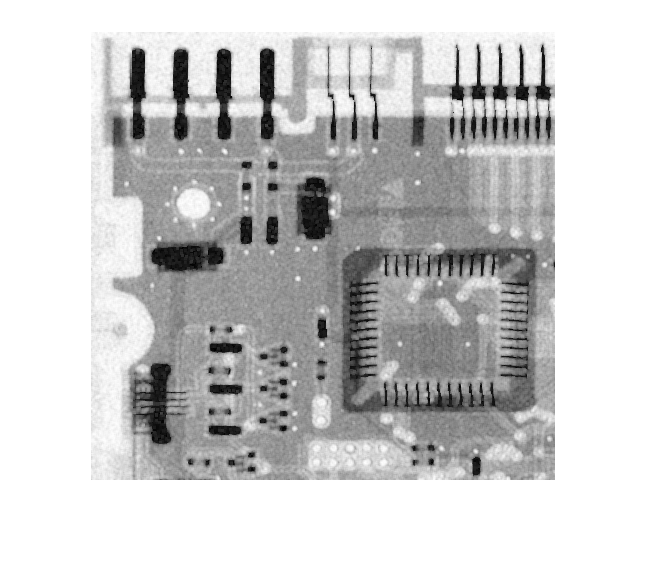

% 过滤椒噪声用 Q 为正的反调和滤波
gp_0_chmean = spfilt(gp_0, 'chmean', 3, 3, 1.5); % q = 1.5
figure;
imshow(gp_0_chmean, []);

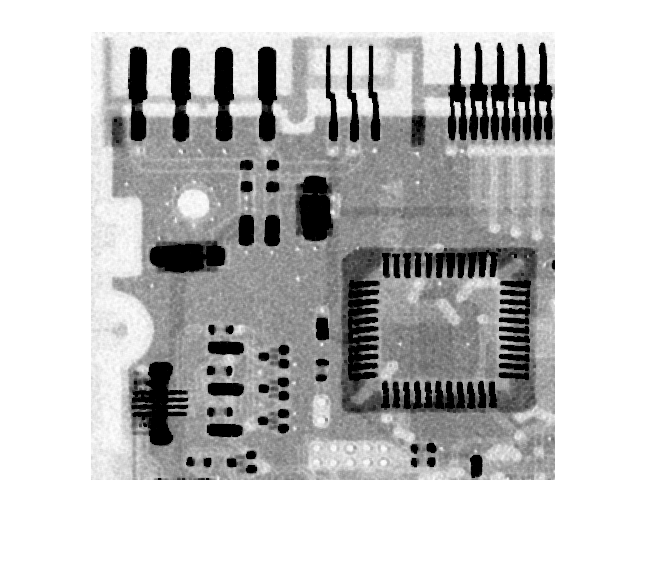

% Q 为负值的反调和滤波处理盐噪声
gp_255_chmean = spfilt(gp_255, 'chmean', 3, 3, -1.5); % q = 1.5
figure;
imshow(gp_255_chmean, []);

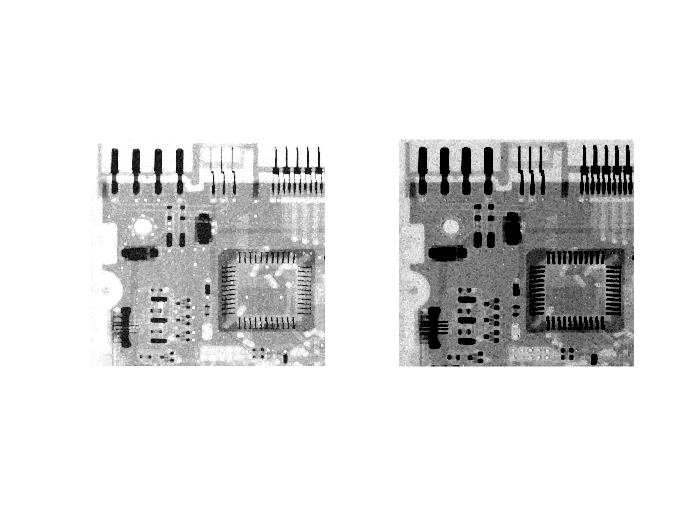

% 滤波器大小都为 3 * 3
% 用最大值滤波对椒噪声(领域内椒噪声是 0，要用最大的代替，所以可以)
gp_0_max = spfilt(gp_0, 'max', 3, 3); % q = 1.5
% 同理，最小值滤波处理盐噪声
gp_255_max = spfilt(gp_255, 'min', 3, 3); % q = 1.5

figure;
subplot(1, 2, 1), imshow(gp_0_max, []), subplot(1, 2, 2), imshow(gp_255_max, []);

% 自适应空间滤波器
% 自适应空间滤波器的两个层级代表的含义 关键在 adpmedian 实现，跳过 例 5.6



## 退化函数建模

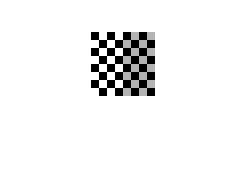

f = checkerboard(8);
figure;
imshow(f, []);

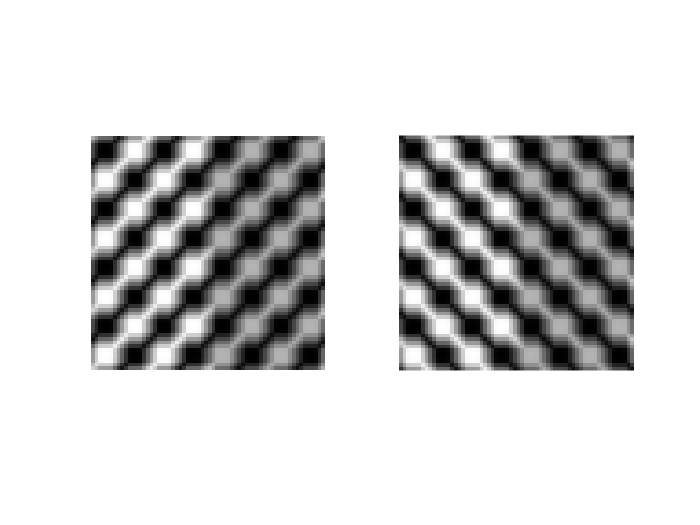

% 用 fspecial 制造运动模糊，退化模型之一
PSF = imfilter(f, fspecial('motion', 7, 45));
gb = imfilter(f, PSF, 'circular');
figure;
% fspecial('motion', len, angle) len 指定运动的长度，theta 以逆时针方向度数指定运动的角度 书上翻译有问题
subplot(1, 2, 1), imshow(imfilter(f, fspecial('motion', 7, 45), 'circular'), []); % 七个像素点，顺时针 45°
subplot(1, 2, 2), imshow(imfilter(f, fspecial('motion', 7, -45), 'circular'), []);

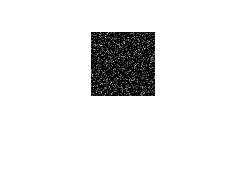

noise = imnoise(zeros(size(f)), 'gaussian', 0, 0.001); % imnoise 可以直接将某噪声加到图像上，此处是单独计算噪声
figure;
imshow(noise, []);

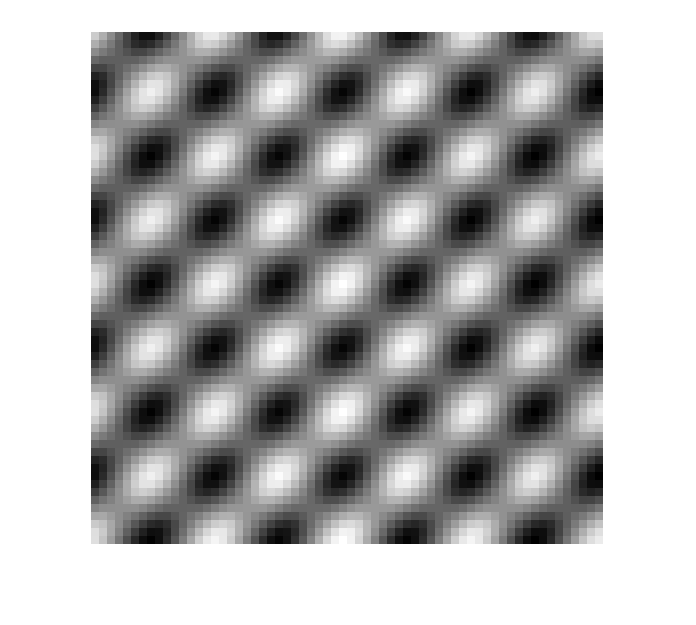

g = gb + noise; % 退化图像模型，H * G + noise(H * G 在空间域代表卷积，故使用 imfilter)
figure;
imshow(pixeldup(g, 8), []);

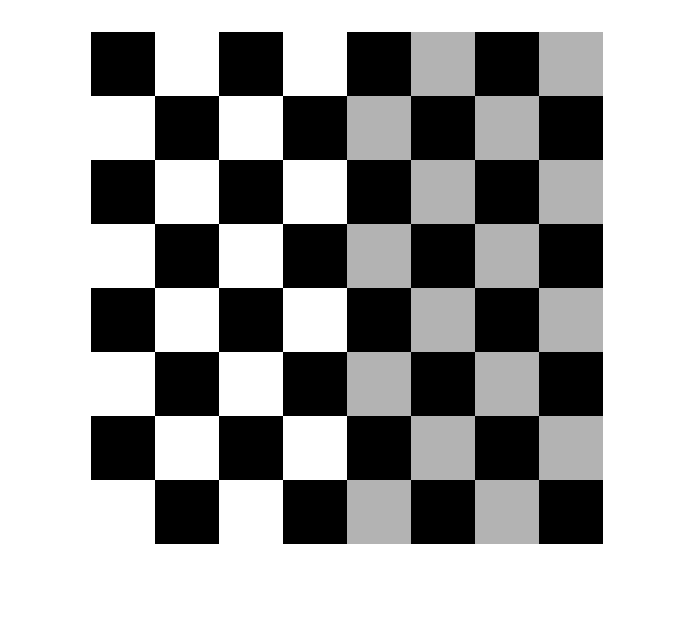

% 利用 pixeldup 复制放大
figure;
imshow(pixeldup(f, 8), []); % 横向纵向都是 8

## 直接逆滤波复原图像

% F = G / H 但这个就要明白是在频率域中实现，然后 F 要进行逆滤波


## 维纳滤波复原图像 

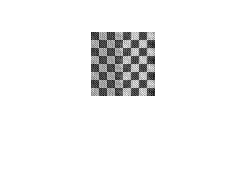

% 在维纳滤波中，可以用一个常量 R = Na / fa 来代替噪信比，或者 R 用交互式方法调整
% g 是上文构造的退化图像
% 相当于直接滤波
fr1 = deconvwnr(g, PSF); 
figure;
imshow(fr1, []);

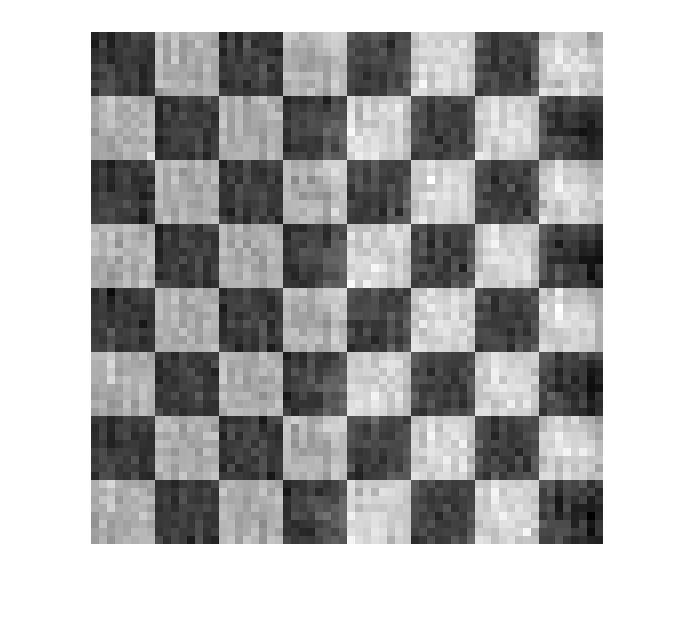

%imshow(pixeldup(fr1, 8), []);
% Sn 噪声的功率谱
% Sf 未退化的图像功率谱
% Na 平均噪声功率
% fA 平均图像功率
Sn = abs(fft2(noise)) .^ 2; % fft2 得到的，是频率矩形，每个点都是经过 DFT， abs 得到频谱
NA = sum(Sn(:)) / prod(size(noise)); % 1/MN * sum{Sn(u, v)}
Sf = abs(fft2(f)) .^ 2;
fA = sum(Sf(:)) / prod(size(f));
R = NA / fA; % 或者交互式获得
fr2 = deconvwnr(g, PSF, R); % 用 R 代替
figure;
imshow(pixeldup(fr2, 8), []);

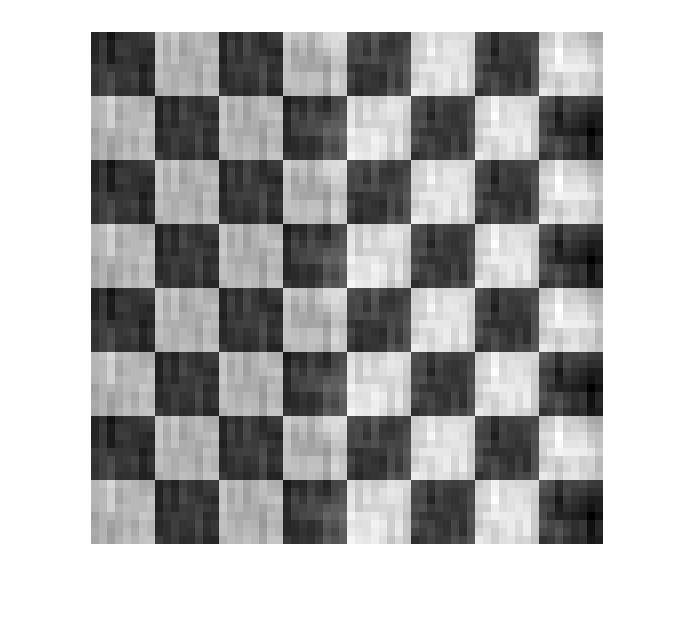

% F(u, v) ^ 2 = dft(f(x, y) · f(x,y)) dft 代表傅里叶变换，· 此处代表相关
% 所以功率谱的逆变换就是自相关函数
% 相关和卷积的差异 表4.3
NCORR = fftshift(real(ifft2(Sn)));
ICORR = fftshift(real(ifft2(Sf)));
% 对图像 I 进行反卷积，其中 ncorr 是噪声的自相关函数，icorr 是原始图像的自相关函数。
%fr3 = deconvwnr(g, PSF, NCORR, ICORR);
fr3 = deconvwnr(g, PSF, real(ifft2(Sn)), real(ifft2(Sf)));
figure;
imshow(pixeldup(fr3, 8), []);

## 遗留问题

% 维纳滤波复原中，为什么和原图相反

## 函数自定义区

function R = imnoise2(type, M, N, a, b) % 产生噪声模型
    if nargin == 1
        a = 0; b = 1;
        M = 1; N = 1;
    elseif nargin == 3
        a = 0; b = 1;
    end
    
    % 详见表 5.1，推导方式：分布函数求逆
    switch lower(type)
        case 'uniform'
            R = a + (b - a) * rand(M, N);
        case 'gaussian'
            R = a + b * randn(M, N); % 为何这里有 线性
        case 'salt & pepper'
            if nargin <= 3
                a = 0.05; b = 0.05;
            end
            if (a + b > 1)
                error('Pa + Pb < 1');
            end
            R(1:M, 1:N) = 0.5; % 0.5 代表不处理，0 代表黑椒，1 代表盐噪声
            X = rand(M, N);
            c = find(X <= a);
            R(c) = 0;
            u = a + b;
            c = find(X > a & X <= u); % Pb * (M * N) 的点
            R(c) = 1;
        case 'lognormal'
            if nargin <= 3
                a = 1; b = 0.25;
            end
            R = a * exp(b * randn(M, N));
        % 这个就是纯正推导出来的
        case 'rayleigh'
            R = a + (-b * log(1 - rand(M, N))) .^ 0.5;
        % 指数
        case 'exponential'
            if nargin <= 3
                a = 1;
            end
            if a <= 0
                error('cao')
            end
            k = -1/a;
            R = k * log(1 - rand(M, N));
        % 
        case 'erlang'
            if nargin <= 3
                a = 2; b = 5;
            end
            if (b ~= round(b) | b <= 0)
                error('positive integer');
            end
            k = -1 / a;
            R = zeros(M, N);
            for j = 1:b
                R = R + k * log(1 - rand(M, N))
            end
        otherwise
            error('unknow')
    end
    
    
    
end

% 计算一幅图像在多边形区域内的直方图
% 注意 roipoly 用法
function [p, npix] = histroi(f, c, r)
    B = roipoly(f, c, r); % 返回是感兴趣区域的二值图像，感兴趣区域都为 1
    p = imhist(f(B)); % 统计感兴趣区域直方图，取 f 的部分区域，利用只含 0 1 的矩阵 mask
    if nargout > 1
        npix = sum(B(:));
    end
end




% 计算 p 内 n 阶矩
function [v,unv] = statmoments(p, n)
%本程序来自冈萨雷斯的matlab书籍
    Lp = length(p);
    if(Lp~=256) & (Lp~=65536)
        error('P must be a 256- or 65536_element vector.');
    end
    G=Lp-1;
    p=p/sum(p);
    p=p(:);
    z=0:G;
    z=z./G;
    m=z*p;
    z=z-m;
    v=zeros(1,n);
    v(1)=m;
    for j=2:n
        v(j)=(z.^j)*p;
    end
    if nargout > 1
        % compute the uncentralized moments.
        unv=zeros(1,n);
        unv(1)=m.*G;
    end
    for j=2:n
        unv(j)=((z*G).^j)*p;
    end
end

% 各类空间滤波， m n 是核的大小
function f = spfilt(g, type, m, n, parameter)
    if nargin == 2
        m = 3; n = 3; Q = 1.5; d = 2;
    elseif nargin ==  5
        Q = parameter; d = parameter;
    elseif nargin ==  4
        Q = 1.5; d = 2;
    else
        error('input error');
    end
    
    switch type
        case 'amean'
            w = fspecial('average', [m n]); % 算术平均，空间滤波器
            f = imfilter(g, w, 'replicate');
        case 'gmean' % 几何平均
            f = gmean(g, m, n);
        case 'hmean' % ?
            f = harmean(g, m, n);
        case 'chmean' % ? 反调和
            f = charmean(g, m, n, Q);
        case 'median'
            f = medfilt2(g, [m n], 'symmetric'); % 中值滤波
        case 'max'
            f= ordfilt2(g, m * n, ones(m, n), 'symmetric'); % 最大值滤波
        case 'min'
            f = ordfilt2(g, 1, ones(m, n), 'symmetric');
        case 'midpoint' % 中点滤波 和 中值滤波？
            f1 = ordfilt2(g, 1, ones(m, n), 'symmetric');
            f2 = ordfilt2(g, m * n, ones(m, n), 'symmetric');
            f = imlincomb(0.5, f1, 0.5, f2);
        case 'atrimmed' % ?
            if (d < 0) | (d / 2 ~= round(d / 2))
                error('nonnegative, integer');
            end
            f = alphatrim(g, m, n, d); % ?
        otherwise
            error('fuck you');
    end
end

function f = gmean(g, m, n)
    inclass = class(g);
    g = im2double(g);
    warning off;
    f = exp(imfilter(log(g), ones(m, n), 'replicate')) .^ ( 1 / m / n);
    warning on;
    f = changeclass(inclass, f);
end

% 注意实现方式，把原图全部先处理，然后用 全 1 的核来滤波
function f = harmean(g, m, n)
    inclass = class(g);
    
    g = im2double(g);
    % 注意滤波器公式是什么
    f = m * n ./ imfilter(1 ./ (g + eps), ones(m, n), 'replicate');
    f = changeclass(inclass, f);
end

% 反调和均值
function f = charmean(g, m, n, q)
    inclass = class(g);
    g = im2double(g);
    f = imfilter(g.^(q+1), ones(m, n), 'replicate'); % ? imfilter 的其他形式
    f = f ./ (imfilter(g.^q, ones(m, n), 'replicate') + eps);
    f = changeclass(inclass, f);
end

% 顺序 - 平衡均值滤波(修正阿尔法均值滤波)
function f = alphatrim(g, m, n, d)
    % alpha
    inclass = class(g);
    g = im2double(g);
    f = imfilter(g, ones(m, n), 'symmetric');
    for k = 1:d/2
        % ?  imsubtract 从数组 X 中的每个元素中减去数组 Y 中的对应元素 负数会舍入到 0
        f = imsubtract(g, ones(m, n), 'symmetric');
    end
    for k = (m*n - (d/2) + 1): m*n
        f = imsubtract(f, ordfilt2(g, k, ones(m, n), 'symmetric'));
    end
    f = f / (m*n - d);
    f = changeclass(inclass, f);
end

function image = changeclass(class, varargin)
    %CHANGECLASS changes the storage class of an image.
    %   I2 = CHANGECLASS(CLASS, I);
    %   RGB2 = CHANGECLASS(CLASS, RGB);
    %   BW2 = CHANGECLASS(CLASS, BW);
    %   X2 = CHANAGECLASS(CLASS, X, 'indexed');
    %   Copyright 1993-2002 The MathWorks, Inc    
    %   $Revision: 1.2 $ $Date:2003/02/19 22:09:58 $

    switch class
    case 'uint8'
       image = im2uint8(varargin{:});
    case 'uint16'
       image = im2uint16(varargin{:});
    case 'double'
       image = im2double(varargin{:});
    otherwise
       error('Unsupported IPT data class.');
    end
end

function f = adpmedian(g, Smax)
    % ADPMEDIAN Perform adaptivev median filtering.
    %   F = ADPMEDIAN(G, SMAX) performs adaptive median filtering of image G.
    %   The median filter starts at size 3-by-3 and iterates up to size
    %   SMAX-by-SMAX. SMAX must be an odd integer greater than 1.
    
    % SMAX must be an odd, positive integer greater than 1.
    if (Smax <= 1)|(Smax/2 == round(Smax/2))|(Smax ~= round(Smax))
        error('Smax must be an odd integer >1.')
    end
    % Initial setup
    f = g;
    f(:) = 0;
    alreadyProcessed = false(size(g));
    % Begin filtering
    for k = 3:2:Smax
        zmin = ordfilt2(g, 1, ones(k,k), 'symmetric');
        zmax = ordfilt2(g, k*k, ones(k,k), 'symmetric');
        zmed = medfilt2(g, [k k], 'symmetric');
        processUsingLevelB = (zmed > zmin) & (zmax > zmed) &  ~alreadyProcessed;
        zB = (g > zmin) & (zmax > g);
        outputZxy = processUsingLevelB & zB;
        outputZmed = processUsingLevelB & ~zB;
        f(outputZxy) = g(outputZxy);
        f(outputZmed) = zmed(outputZmed);
        
        alreadyProcessed = alreadyProcessed | processUsingLevelB;
        if all(alreadyProcessed(:))
            break;
        end
    end
    % Output zmed for any remaining unprocessed pixels. Note that this zmed was
    % computed using a window of size Smax-by-Smax, which is the final value of
    % k in the loop.
    f(~alreadyProcessed) = zmed(~alreadyProcessed);
end

% 
function B = pixeldup(A, m, n)
    %PIXELDUP Duplicates pixels of an image in both directions.
    %   B = PIXELDUP(A, M, N) duplicates each pixel of A M times in the
    %   vertical direction and N times in the horizontal direction.
    %   Parameters M and N must be integers.  If N is not included, it
    %   defaults to M.
    
    %   Copyright 2002-2004 R. C. Gonzalez, R. E. Woods, & S. L. Eddins
    %   Digital Image Processing Using MATLAB, Prentice-Hall, 2004
    %   $Revision: 1.5 $  $Date: 2005/01/03 00:01:28 $
    
    % Check inputs.
    if nargin < 2 
       error('At least two inputs are required.'); 
    end
    if nargin == 2 
       n = m; 
    end
    
    % Generate a vector with elements 1:size(A, 1).
    u = 1:size(A, 1);
    
    % Duplicate each element of the vector m times.
    m = round(m); % Protect against nonintegers.
    u = u(ones(1, m), :);
    u = u(:);
    
    % Now repeat for the other direction.
    v = 1:size(A, 2);
    n = round(n);
    v = v(ones(1, n), :);
    v = v(:);
    B = A(u, v);
end


% imnoise3 跳过